Let us look at which eigendirection contributes most to SNR.

In visual cortex (according to Oleg's paper), the answer is the third eigenmode of noise.

First let's load the sessions database:

org = Org;
org.load_definitions;

Let's look at session #70 first.

Look at the noise eigenvalues of the covariance matrix, the loadings of the signal vector (not unit vector) on the eigenvectors, and the SNR along each eigenvector.

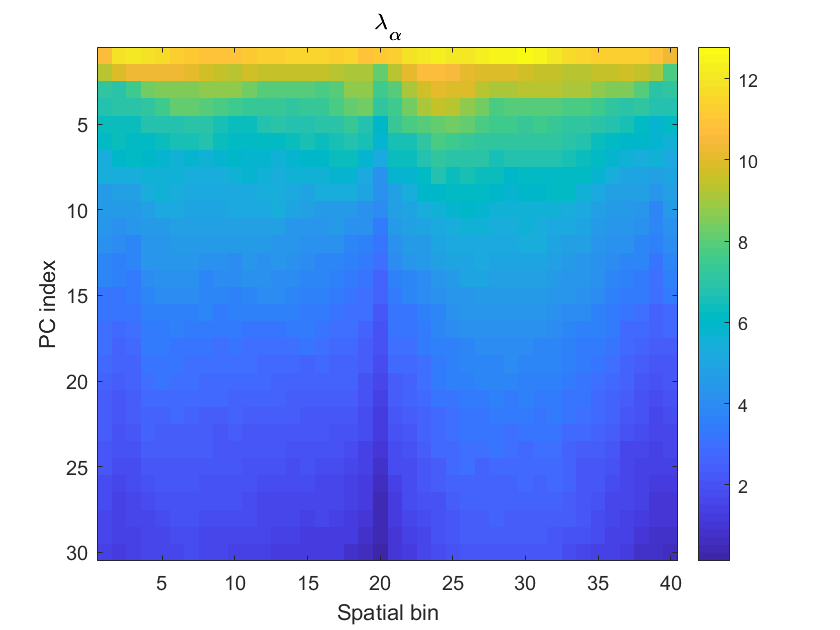

s_ID = 70;

cut = @(x)x(1:30,:);

figure;
%subplot(3,1,1);
imagesc(cut(org.sess_by_bins('lambda', s_ID)));
set(gca, 'ColorScale', 'log');
xlabel 'Spatial bin'
ylabel 'PC index'
title '\lambda_\alpha'
colorbar;

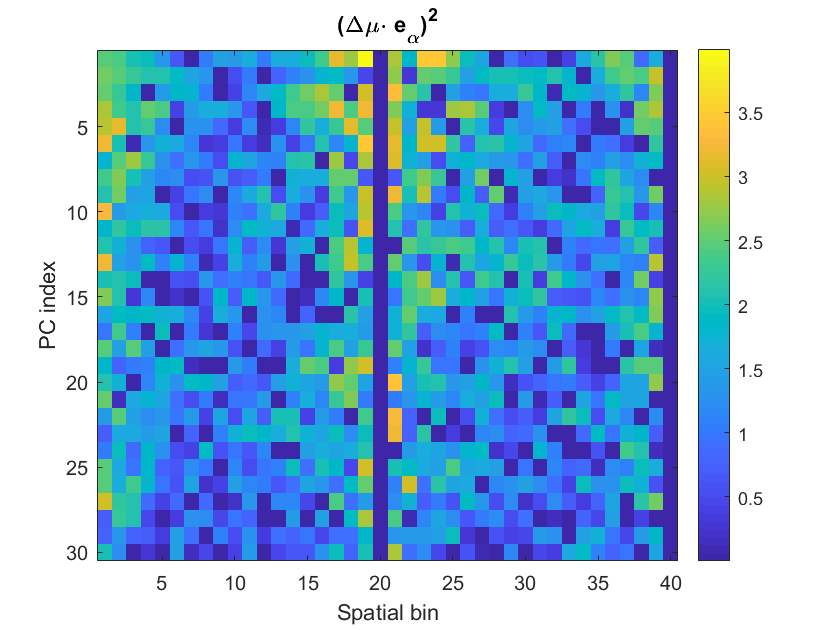


figure;%subplot(3,1,2);
imagesc(cut(org.sess_by_bins('full_loadings', s_ID)));
set(gca, 'ColorScale', 'log');
xlabel 'Spatial bin'
ylabel 'PC index'
title '(\Delta\mu\cdot e_\alpha)^2'
colorbar;

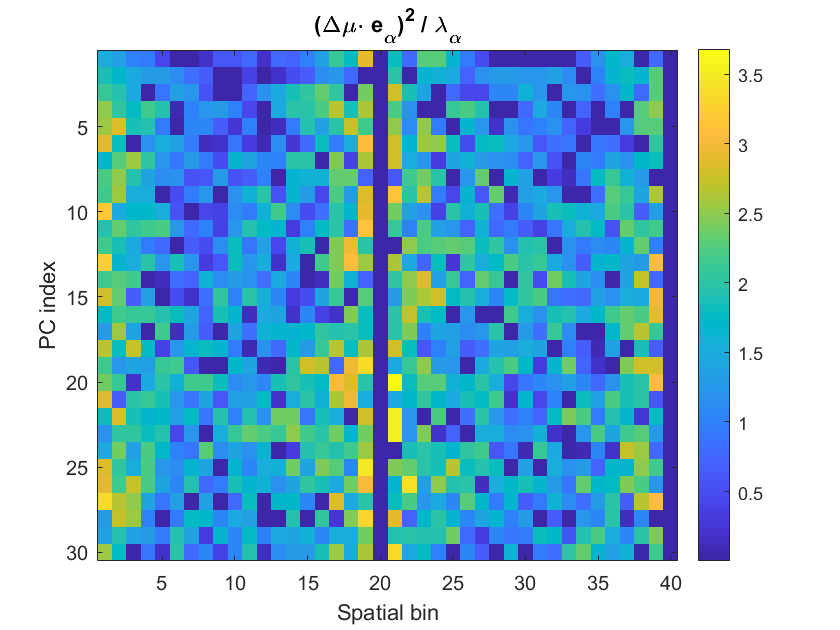


figure;%subplot(3,1,3);
imagesc(cut(org.sess_by_bins('eigen_snr',s_ID)));
set(gca, 'ColorScale', 'log');
xlabel 'Spatial bin'
ylabel 'PC index'
title '(\Delta\mu\cdot e_\alpha)^2 / \lambda_\alpha'
colorbar;

It looks like the earlier PCs have less SNR. Let's check if it generalizes.

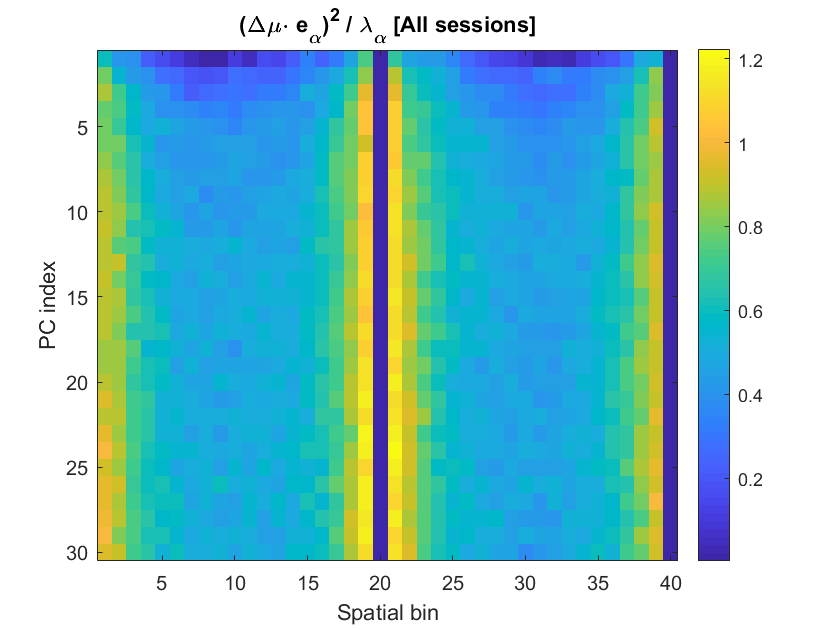

figure;
imagesc(cut(org.all_by_bins('eigen_snr')));
set(gca, 'ColorScale', 'log');
xlabel 'Spatial bin'
ylabel 'PC index'
title '(\Delta\mu\cdot e_\alpha)^2 / \lambda_\alpha [All sessions]'
colorbar;

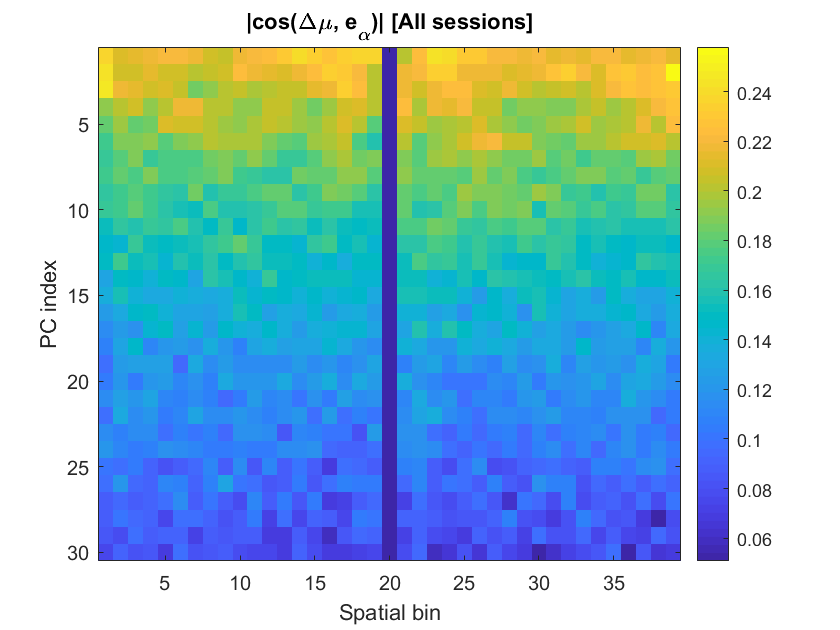

figure;
imagesc(cut(org.all_by_bins('loadings')));
set(gca, 'ColorScale', 'log');
xlabel 'Spatial bin'
ylabel 'PC index'
title '|cos(\Delta\mu, e_\alpha)| [All sessions]'
colorbar;

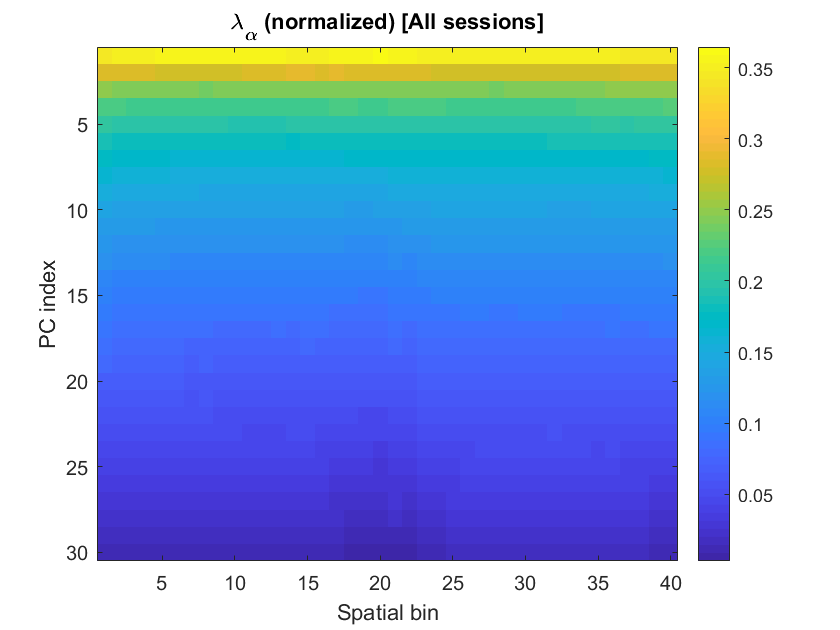

figure;
imagesc(cut(org.all_by_bins('lambda_normed')));
set(gca, 'ColorScale', 'log');
xlabel 'Spatial bin'
ylabel 'PC index'
title '\lambda_\alpha (normalized) [All sessions]'
colorbar;

It looks like the effect generalizes. This result is qualitatively different from the cortex.